# Monte Carlo 法による数値積分

clear all; clf;

## 乱数を用いた数値計算・シミュレーション

Monte Carlo法は，乱数を用いて数値計算・シミュレーションを行う手法の総称である．

以下ではMonte Carlo法の一例として，円周率の計算を取り上げる．

### （例）円周率の計算 ← 領域の面積計算

**下図**のように正方領域 $0<x,y<1$ に $N$ 個の点をランダムに打つことを考える．

このとき1つの点が半径1の四分円（図中の青い領域）に含まれる確率は，四分円の面積 $\pi/4$ の正方形の面積1に対する比で与えられ， $\pi/4$ となる．

このため $N$ が十分大きければ，四分円に含まれる点の総数を $n$ とするとき，その割合 $n/N$ は近似的に $\pi/4$ に一致すると期待される．

このことを利用すれば，円周率 $\pi$ の値を近似的に求めることができる．

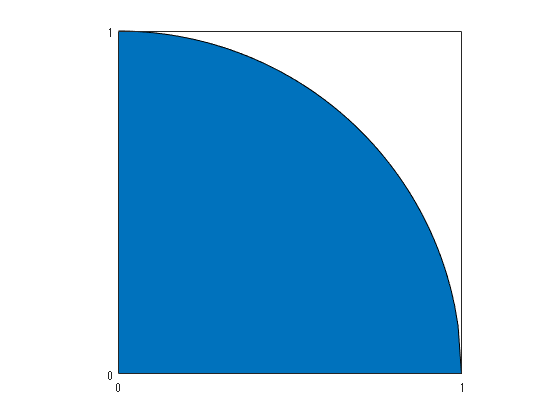

x = 0:0.01:1;
y = sqrt(1-x.*x);
area(x,y)
pbaspect([1 1 1])
xticks([0 1])
yticks([0 1])

以下では実際に，点を打つ回数 $N$ を様々に変えたときの割合 $n/N$ を数値シミュレーションによって調べよう．

結果は回数 $N$ を横軸に，$4n/N$ を縦軸にとって表示しており，回数 $N$ が増えるにつれて $4n/N$ の値が円周率 $\pi$ に近づく様子が見て取れる．

pr = 0; % 円の中に入る確率
itr1 = 0; % 繰り返し回数
itr2 = 0; % 円の中に入る回数
pp = [];
xp0 = [];
yp0 = [];
xp1 = [];
yp1 = [];
grp = [];
N = 4000

N = 4000

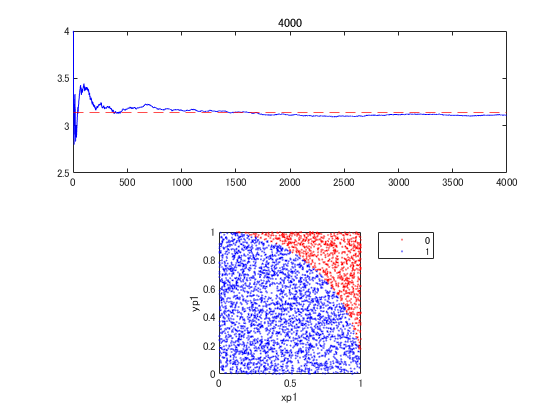


while itr1 < N
    itr1 = itr1 + 1;
    xr = rand();
    yr = rand();
    xp1 = horzcat(xp1, xr);
    yp1 = horzcat(yp1, yr);
    if xr*xr + yr*yr < 1
        itr2 = itr2 + 1;
        grp = horzcat(grp, 1);
    else
        grp = horzcat(grp, 0);
    end
    pr = itr2 / itr1;
    pp = horzcat(pp, pr);
    if (rem(itr1, 20)==0)
        tiledlayout(2,1) % Requires R2019b or later
        nexttile
        plot(1:itr1,4*pp,'b-')
        yline(pi,'r--')
        title(itr1);

        nexttile
        gscatter(xp1, yp1, grp,"rb","..", [2 2]);
        legend('Location','northeastoutside')
        %scatter(xp, yp);
        xlim([0 1])
        ylim([0 1])
        pbaspect([1 1 1])

        drawnow
        hold on
    end
end
hold off